# Trim, Linearise and design a Control system for the ***Lagrangian*** quadcopter model:

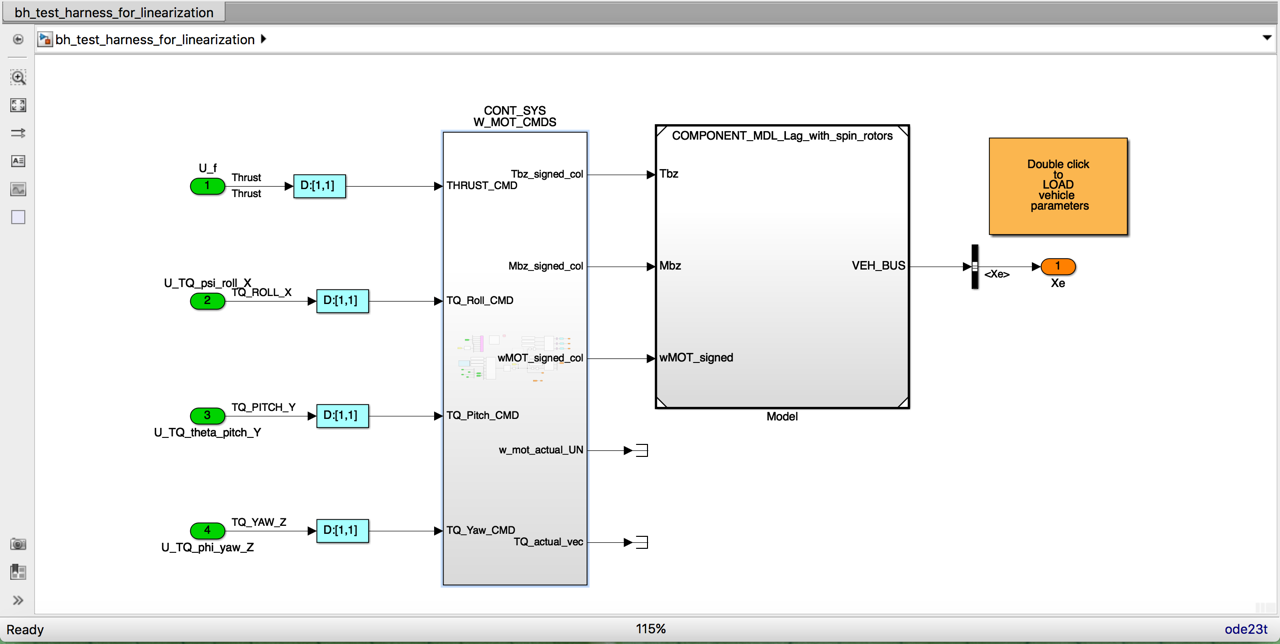

In this task we're going to linearise our **Simulink** quadcopter model. We're going to do this because we'd like to apply some "state space" control design techniques in order to design a control system for the quadcopter.  And as you know, these control techniques require a LINEAR plant model.  The workflow that we'll follow is this:

- We'll find an operating point for the pendulum. An operating point is characterized by the state(X), the input(U) and the output(Y).    We'll look specifically for an operating point that corresponds to steady state, ie: where the pendulum's state derivatives are ZERO. This is referred to as finding a **TRIMMED operating point**.

- We'll then use this TRIMMED operating point to calculate a **linearised** version of the quadcopter model.

- Finally, we'll then use this linearised model to design a full state feedback control system using the Linear Quadratic Integrator (LQI) technique.

`Bradley Horton : 28-Jun-2017, bradley.horton@mathworks.com.au`

# 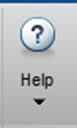 Take a moment !

If you're interested in reading about how to linearize a NON linear plant model.  Use the MATLAB HELP browser and try this simple text search

- `linearize control system`

HINT:  today we'll be using the functions:

- `operspec,   findop,   linearize`

## Load the model parameters:

bh_quad_params
bh_create_LAG_SL_VEH_BUS 
whos

  Name                 Size            Bytes  Class           Attributes

  P_elec               1x1               352  struct                    
  P_mot                1x1              1232  struct                    
  P_mot_alone          1x1              1232  struct                    
  P_mot_vec            4x1              3584  struct                    
  P_one_prop           1x1               880  struct                    
  P_rot                1x1               592  struct                    
  P_veh                1x1              1536  struct                    
  P_veh_no_props       1x1              1536  struct                    
  SL_VEH_BUS           1x1               635  Simulink.Bus              
  XYZ_circ_mat        88x3              2112  double                    
  X_TS_OBJ             1x1               569  timeseries                
  Y_TS_OBJ             1x1               569  timeseries                
  Z_TS_OBJ             1x1               569  time

warning('off')

## The name of the SIMULINK model that we'll linearise:

model  = 'bh_test_harness_for_linearization';
open_system(model)

## Create the operating point specification object.

opspec = operspec(model);

Evaluating MaskInitialization for 'bh_test_harness_for_linearization/CONT_SYS W_MOT_CMDS/W2_checker/Compare To Constant': 'blkName = gcb;  if strcmp(get_param(gcbh,'OutDataTypeStr'),'boolean') 	setValue = 'boolean'; else 	s...'.
Evaluating callback 'MaskParameterCallback' for bh_test_harness_for_linearization/CONT_SYS W_MOT_CMDS/W2_checker/Compare To Constant
Callback: sl('zeroCrossEnable', gcbh);
Evaluating MaskInitialization for 'bh_test_harness_for_linearization/CONT_SYS W_MOT_CMDS/W2_checker/Compare To Constant': 'blkName = gcb;  if strcmp(get_param(gcbh,'OutDataTypeStr'),'boolean') 	setValue = 'boolean'; else 	s...'.
Evaluating MaskInitialization for 'COMPONENT_MDL_Lag_with_spin_rotors/bh_6DOF (Euler Angles, Lagrangian, Multi_body)': ' '.


In our operating point specification, note the following:

- Our GREEN root level INPORT blocks are the system inputs 

- Our ORANGE root level OUTPORT blocks are the system outputs 

display(opspec)

opspec =  Operating point specification for the Model bh_test_harness_for_linearization.
 (Time-Varying Components Evaluated at time t=0)

States: 
----------
    x    Known    SteadyState    Min     Max    dxMin    dxMax
    _    _____    ___________    ____    ___    _____    _____

(1.) DOT_phi
    0    false       true        -Inf    Inf    -Inf      Inf 
(2.) 

For each of our model states we can specify "desired" values for each of the following.  

- `x           :`   initial guess for state value

- `SteadyState :`   a logical indicating we are looking for a dx=0 final value

- `Min         :`   minimum bound for state value

- `Max         :`   maximum bound for state value

For our problem, we're going to look for an operating point where ALL of our states are at SteadyState (ie: dx/dt=0)

%[ opspec.States(1).SteadyState]
%[ arrayfun(@(a) (a.SteadyState), opspec.States) ].'

Our trimming function(coming up next) will then look for an operating point that satisfies this specification:

## Look for the steady state operating point.

opt           = findopOptions('DisplayReport','off');
[op,opreport] = findop(model,opspec, opt);

Evaluating callback 'MaskParameterCallback' for bh_test_harness_for_linearization/CONT_SYS W_MOT_CMDS/W2_checker/Compare To Constant
Callback: sl('zeroCrossEnable', gcbh);
Evaluating MaskInitialization for 'bh_test_harness_for_linearization/CONT_SYS W_MOT_CMDS/W2_checker/Compare To Constant': 'blkName = gcb;  if strcmp(get_param(gcbh,'OutDataTypeStr'),'boolean') 	setValue = 'boolean'; else 	s...'.
Evaluating MaskInitialization for 'COMPONENT_MDL_Lag_with_spin_rotors/bh_6DOF (Euler Angles, Lagrangian, Multi_body)': ' '.


Review our trimmed OPERATING point and NOTE the following:

- We have indeed found a steady state operating point because the state derivatives are either zero OR very small $O(10^{-7})$

- In this trimmed pose, ALL of the system outputs are ZERO.

- To maintain this trimmed pose we need to supply an INPUT force ... which is the force to counter gravity. 

display(opreport)

opreport =  Operating point search report for the Model bh_test_harness_for_linearization.
 (Time-Varying Components Evaluated at time t=0)

Operating point specifications were successfully met.
States: 
----------
    Min          x         Max    dxMin        dx         dxMax
    ____    ___________    ___    _____    ___________    _____

(1.) DOT_phi
    -Inf              0    Inf      0       9.7898e-52      0  
(2.) 

## Linearize the model about this operating point:

Next we'll linearise our model about this trimmed operating point:

my_LIN_PLANT = linearize(model,op);

Evaluating callback 'MaskParameterCallback' for bh_test_harness_for_linearization/CONT_SYS W_MOT_CMDS/W2_checker/Compare To Constant
Callback: sl('zeroCrossEnable', gcbh);
Evaluating MaskInitialization for 'bh_test_harness_for_linearization/CONT_SYS W_MOT_CMDS/W2_checker/Compare To Constant': 'blkName = gcb;  if strcmp(get_param(gcbh,'OutDataTypeStr'),'boolean') 	setValue = 'boolean'; else 	s...'.
Evaluating MaskInitialization for 'COMPONENT_MDL_Lag_with_spin_rotors/bh_6DOF (Euler Angles, Lagrangian, Multi_body)': ' '.


Note the names of the **INPUTS** "U"  

my_LIN_PLANT.InputName

ans = 4×1 cell array
    {'U_f'               }
    {'U_TQ_psi_roll_X'   }
    {'U_TQ_theta_pitch_Y'}
    {'U_TQ_phi_yaw_Z'    }


and the **OUTPUTS** "Y" 

my_LIN_PLANT.OutputName

ans = 3×1 cell array
    {'bh_test_harness_for_linearization/Xe(1,1)'}
    {'bh_test_harness_for_linearization/Xe(2,1)'}
    {'bh_test_harness_for_linearization/Xe(3,1)'}


and the **STATES** "X"

my_LIN_PLANT.StateName

ans = 12×1 cell array
    {'DOT_phi'  }
    {'DOT_theta'}
    {'DOT_psi'  }
    {'DOT_Xe'   }
    {'DOT_Ye'   }
    {'DOT_Ze'   }
    {'phi'      }
    {'theta'    }
    {'psi'      }
    {'Xe'       }
    {'Ye'       }
    {'Ze'       }


Get ready for a simulation:

x0 = [zeros(1,12)];

Check if the linearised system is Full state Feedback(FSFB) Controllable. If the system is NOT FSFB controllable it means that we can not arbitrarily position the system poles.  We can still position them ... but NOT arbitrarily.

A = my_LIN_PLANT.A;
B = my_LIN_PLANT.B;
C = my_LIN_PLANT.C;
D = my_LIN_PLANT.D;

co = ctrb(A,B);
if(rank(co) ~= size(A,1) )
    error('###_ERROR: the system is NOT FSFB controllable');
end

And close the model:

close_system(model)

## Control design:

We'll use the approach described by the LQI() function, ie::

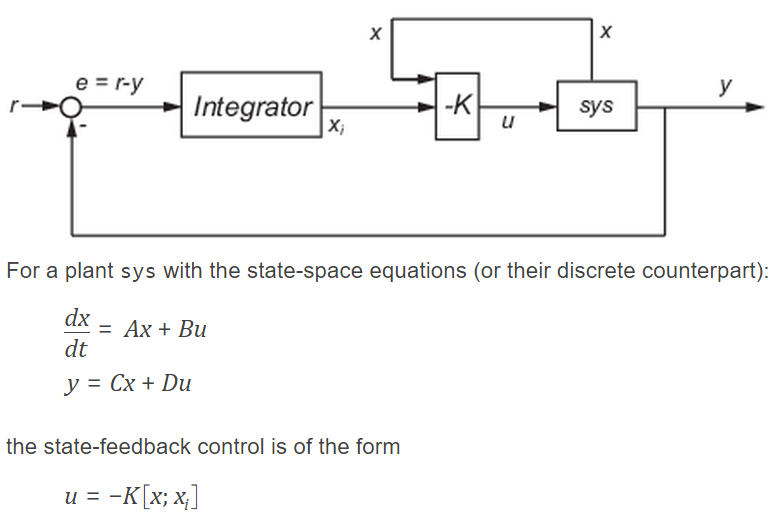

Note that:  

- 
$$K\in R^{N_u \times \left(N_x +N_y \right)}$$


Nx = size(A,1);  Nu = size(B,2);  Ny = size(C,1);

Now design a full state feedback controller using `LQI()`. NOTE the following:

- you will need to experiment with the Q,R weighting matrices

- alternatively consider using place() to manually specify the position of the poles

% Q = 0.05*diag(ones(1, Nx+Ny)); % 0.01 is good with motors
% R =  1*diag(ones(1, Nu));
tmp        = 0.001*[ones(1, Nx+Ny)];
tmp(13:15) = [5,5,20];  % weight the "error" states for X,Y,Z 
                        % that we want to drive to ZERO
Q = diag(tmp); 
R =  1*diag(ones(1, Nu));
[K,~,~] = lqi(my_LIN_PLANT,Q,R,[])

K =     0.0000   -0.0000    0.0000   -0.0000   -0.0000    3.1334   -0.0000   -0.0000    0.0000    0.0000   -0.0000    5.2941   -0.0000   -0.0000   -4.4721
   -0.0000   -0.0000    0.1266   -0.0000   -0.5046    0.0000   -0.0000   -0.0000    1.0164   -0.0000   -1.5026    0.0000    0.0000    2.2361   -0.0000
   -0.0000    0.1266    0.0000    0.5046   -0.0000   -0.0000   -0.0000    1.0164    0.0000    1.5026   -0.0000   -0.0000   -2.2361    0.0000    0.0000
    0.0432    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0316    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000


What does the gain matrix K, look like?

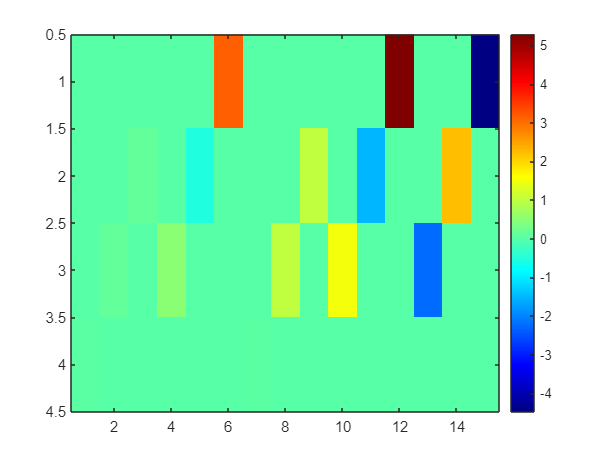

hfig = figure;
colormap(hfig,jet)
imagesc(K); colorbar

What do the closed loop poles look like ?

A_hat = [  A,   zeros(Nx,Ny);
          -C,   zeros(Ny,Ny) ];
      
B_hat = [ B;
          zeros(Ny,Nu) ];
p_lqi = esort( pole( ss((A_hat-B_hat*K),[],[],[]) ) )

p_lqi =   -0.8449 + 1.4631i
  -0.8449 - 1.4631i
  -1.1539 + 0.0000i
  -1.6624 + 4.4114i
  -1.6624 - 4.4114i
  -1.6624 + 4.4114i
  -1.6624 - 4.4114i
  -1.6897 + 0.0000i
  -2.0042 + 0.0000i
  -4.2241 + 2.6211i


Now test the design using ONLY the linearised plant:

%open_system('bh_lag_quad_TEST_LINEAR_SYS_CONT_DESIGN')

Now save the results:

RESULTS_FILE_NAME = 'bh_CONT_DES_RESULTS_LQI_quadcopter.mat';
the_state_names =  my_LIN_PLANT.StateName;
save(RESULTS_FILE_NAME, 'K', 'the_state_names')

## Should we commit this design ?

If you want to commit this design then run the following code also:

tf_i_will_commit_design = true;
if(true==tf_i_will_commit_design)
    RESULTS_FILE_NAME = 'bh_CONT_DES_RESULTS_LQI_quadcopter.mat';
    the_state_names =  my_LIN_PLANT.StateName;
    save(RESULTS_FILE_NAME, 'K', 'the_state_names')
end